This is a livescript for the adaptive MC method in Task 1, after the Richardson stuff.

tic

M = 40000;
I = 100;
N = 10;
c_alpha = 1.96;
samples = zeros([1 M]);
MC_est = zeros([1 M]);
MC_var = zeros([1 M]);
CLT = zeros([1 M]);

for k=progress(1:M)
    samples(k) = QoI(I, 2, 'infinity');
    MC_est(k) = 1/k*sum(samples(1:k));
    if k>1
        MC_var(k) = (1/(k-1))*sum((samples(1:k) - MC_est(k)).^2);

    end
end

Processing:  000%  |                                  | 0/40000it [00:00:00<Inf:NaN:NaN, Inf it/s]


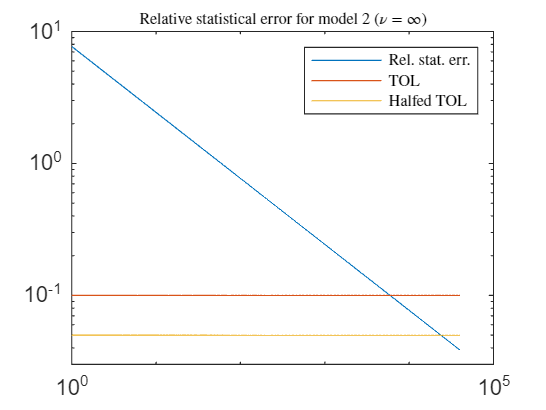


for i=1:M
    CLT(i) = (c_alpha*sqrt(MC_var(end)))/(sqrt(i)*abs(MC_est(end)));
end

loglog(1:M, CLT, 1:M, TOL*ones([M 1]), 1:M, 0.5*TOL*ones([1 M]))
title('Relative statistical error for model 2 ($\nu=\infty$)', 'Interpreter', 'latex', fontsize=7)
legend('Rel. stat. err.', 'TOL', 'Halfed TOL', 'Interpreter', 'latex', fontsize=7)
ylim([0.03 10])
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "HW1_Part2_staterr_M2_inf")


toc

Elapsed time is 55.754657 seconds.
